clear 
clc

fileID = fopen('data_2024-05-15 17:48:54.683902');
data = fread(fileID,'single') 

data = 1.0e+09 *

    0.0001
   -0.0001
   -0.0003
    0.0017
    0.0023
    0.0024
    0.0025
    0.0027
    0.0031
    0.0023


%data = data/max(data)*2; 
data = data/power(2,31);
fs = 41.6667e3;
numMics = 8;
numSamples = 190;
onePacketLength = numSamples*numMics 

onePacketLength = 1520

numPacketsInData = floor(length(data)/onePacketLength)

numPacketsInData = 2304

splitdata = zeros(numSamples,numMics);
for i = 0:numPacketsInData-1
    splitdata = [splitdata; reshape(data(i*onePacketLength+1:(i+1)*onePacketLength),[],numMics)];
end
splitdata = splitdata(numSamples:end,:)'

splitdata =          0    0.0000   -0.0001   -0.0001    0.0008    0.0011    0.0011    0.0012    0.0013    0.0014    0.0011    0.0014    0.0012    0.0011    0.0012    0.0013    0.0013    0.0011    0.0007    0.0008    0.0012    0.0010    0.0015    0.0013    0.0004    0.0003    0.0003   -0.0001   -0.0000    0.0004    0.0009    0.0012    0.0012    0.0013    0.0012    0.0017    0.0024    0.0018    0.0017    0.0022    0.0024    0.0026    0.0026    0.0032    0.0037    0.0037    0.0035    0.0027    0.0020    0.0019
         0    0.0020    0.0023    0.0025    0.0023    0.0017    0.0010    0.0004    0.0005    0.0005    0.0004    0.0008    0.0014    0.0017    0.0014    0.0014    0.0020    0.0026    0.0026    0.0027    0.0030    0.0032    0.0032    0.0033    0.0032    0.0026    0.0027    0.0023    0.0018    0.0011    0.0003    0.0001    0.0004    0.0004    0.0000    0.0002    0.0001   -0.0001    0.0002    0.0005    0.0001    0.0003    0.0007    0.0009    0.0017    0.0023    0.0024    0.0022    0.0

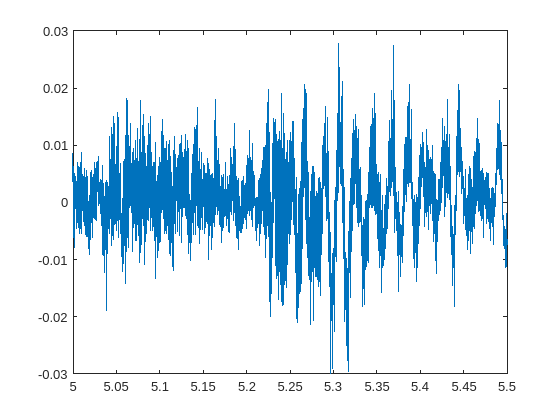


t = (0:1/fs:(length(splitdata)-1)/fs);
plot(t,splitdata(8,:))
hold on
xlim([5 5.5])
%ylim([-0.2 0.2])
hold off

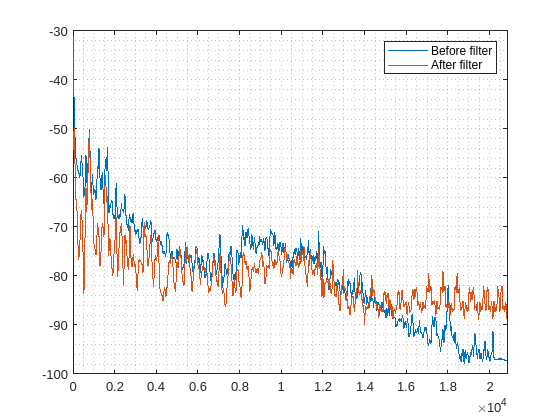


%sound(splitdata(8,:),41e3)

[p_mic0, f_mic0] = pspectrum(splitdata(1,:),fs);
[p_mic1, f_mic1] = pspectrum(splitdata(2,:),fs);
[p_mic2, f_mic2] = pspectrum(splitdata(3,:),fs);
[p_mic3, f_mic3] = pspectrum(splitdata(4,:),fs);
[p_mic4, f_mic4] = pspectrum(splitdata(5,:),fs);
[p_mic5, f_mic5] = pspectrum(splitdata(6,:),fs);
[p_mic6, f_mic6] = pspectrum(splitdata(7,:),fs);
[p_fir, f_fir] = pspectrum(splitdata(8,:),fs);

%plot(f_mic0,10*log10(p_mic0))
%hold on
%plot(f_mic3,10*log10(p_mic3))
%plot(f_mic6,10*log10(p_mic6))
plot(f_mic6,10*log10((p_mic0 + p_mic1 + p_mic2 + p_mic3 + p_mic4 + p_mic5 + p_mic6)*1/7))
hold on
%plot(f_mic0,10*log10(p_mic0))
plot(f_fir,10*log10(p_fir))
legend('Before filter', 'After filter')
%legend('Mic 0', 'Mic 3', 'Mic 6', 'Output of FIR1')
xlim([0 fs/2])
grid minor
hold off